# TITLE: Signal Modulation and Detection in an AWGN Channel with Laser Phase Noise (Pilot-based CPE)

Authors: Fernando Guiomar [guiomar@av.it.pt](guiomar@av.it.pt) 

## Initialization

clear;
clear global;
close all;
clc;

% Load Libraries:
addpath(genpath('..\..\..\'));

global PROG;
PROG.showMessagesLevel = 2;
initProg();

Current Date: 10-Nov-2019 01:22:55


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                      PROGRAM INITIALIZATION                      %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%


RGB = fancyColors();

## Input Parameters

SIG.M = 16;                 % QAM constellation size
SIG.symRate = 60e9;         % total symbol-rate of the signal
SIG.modulation = 'QAM';     % modulation type [QAM/PAM]
SIG.rollOff = 0.1;          % roll-off factor
SIG.nPol = 1;               % number of polarizations
SIG.nSyms = 2^17;           % total number of simulated symbols
nSpS = 2;                   % number of samples per symbol
laserLW = 1e6;              % laser linewidth [Hz]

pilotRate = 31/32;
useCPE2 = false;

SNR_dB = ber2snr(1e-3,SIG.M);   % SNR in dB

## Set Transmitter Parameters

#### Signal Parameters:

TX.SIG = setSignalParams('symRate',SIG.symRate,'M',SIG.M,...
    'nPol',SIG.nPol,'nBpS',log2(SIG.M),'nSyms',SIG.nSyms,...
    'roll-off',SIG.rollOff,'modulation',SIG.modulation);

#### Modulation Parameters:

TX.QAM = QAM_config(TX.SIG);

#### Bit Parameters:

TX.BIT.source = 'randi';
TX.BIT.seed = 1;

#### Pulse Shaping Filter Parameters:

TX.PS.type = 'RRC';
TX.PS.rollOff = TX.SIG.rollOff;
TX.PS.nTaps = 128;

#### DAC Parameters:

TX.DAC.RESAMP.sampRate = nSpS*TX.SIG.symRate;

#### LASER Parameters:

TX.LASER.linewidth = laserLW;

#### DSP Pilots Parameters:

TX.PILOTS.active = true;
TX.PILOTS.rate = pilotRate;
TX.PILOTS.option = 'outerQPSK';
% TX.PILOTS.scaleFactor = 1;

## Calculate Transmitted Net Bit-Rate

bitRate_net = SIG.symRate * log2(SIG.M) * TX.PILOTS.rate;
fprintf('Transmitted net bit-rate: %1.4f Gbps\n',bitRate_net*1e-9);

Transmitted net bit-rate: 232.5000 Gbps


## Generate Tx Bits

TX.BIT.txBits = Tx_generateBits(SIG.nSyms,TX.QAM.M,TX.QAM.nPol,TX.BIT);

## Generate Transmitted Symbols

[S.tx,TX.BIT.txSyms] = Tx_QAM(TX.QAM,TX.BIT.txBits);

#### Plot Transmitted Constellation Symbols:

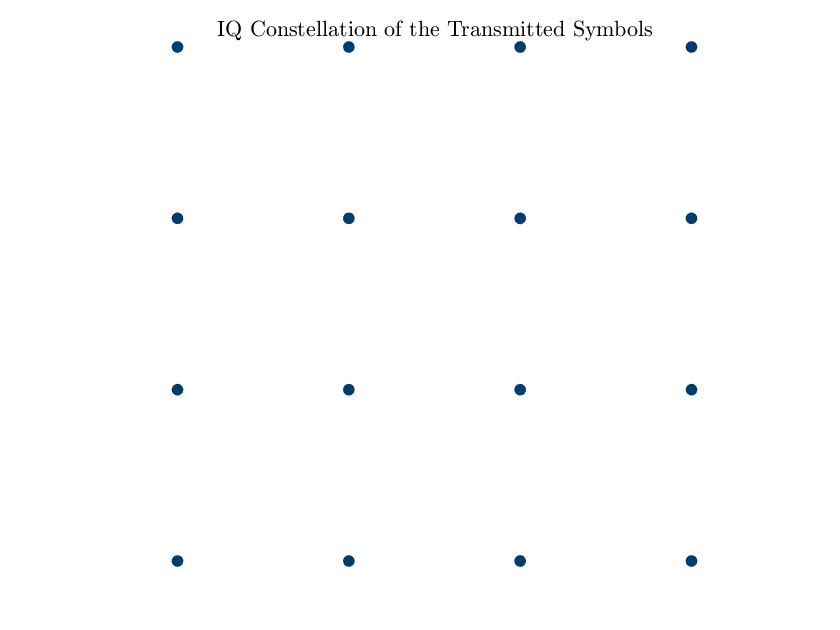

scatterPlot(S.tx,'markersize:sig',20);
title('IQ Constellation of the Transmitted Symbols','interp','latex')

## Add DSP Pilots

if isfield(TX,'PILOTS') && TX.PILOTS.active && TX.PILOTS.rate < 1
    [S.tx,TX.PILOTS] = Tx_addPilots(S.tx,TX.PILOTS,TX.QAM.IQmap);
    TX.QAM.meanConstPower = mean(abs(S.tx).^2,2);
    TX.QAM.maxConstPower = max(abs(S.tx).^2,[],2);
end

#### Plot Pilot Symbols:

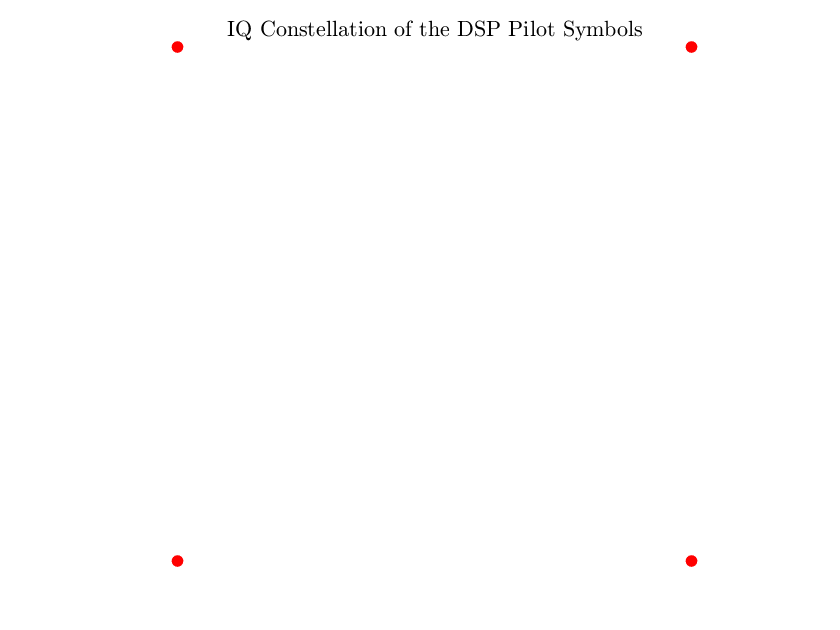

scatterPlot(TX.PILOTS.pilotSequence,'markersize:sig',20,'markercolor:sig','r');
title('IQ Constellation of the DSP Pilot Symbols','interp','latex')

## Pulse Shaping

[S.txSC,TX.PS] = pulseShaper(S.tx,nSpS,TX.PS);

#### Plot Pulse Shaping Taps

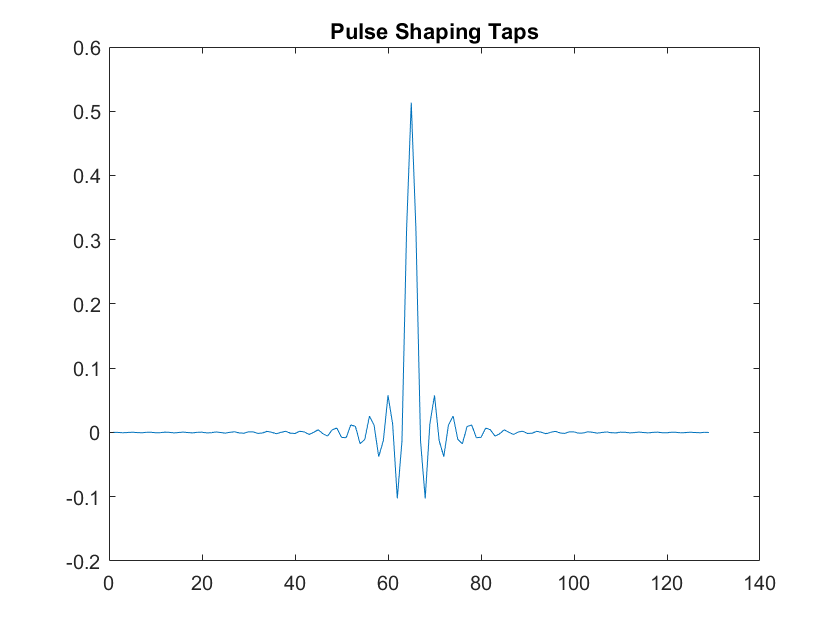

figure();
plot(TX.PS.W);
title('Pulse Shaping Taps')

#### Plot Signal Spectrum

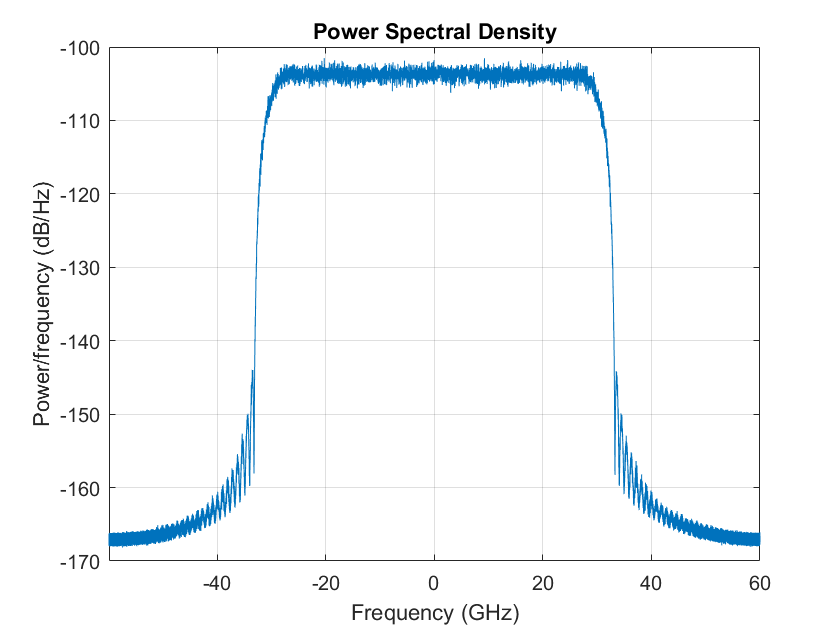

figure();
pwelch(S.txSC(1,:),1e4,[],[],TX.DAC.RESAMP.sampRate,'centered')

## Digital-to-Analog Converter

Fs_SC = nSpS * SIG.symRate;
[S.txSC,TX.DAC] = Tx_DAC(S.txSC,TX.DAC,Fs_SC);

## Apply Laser

nSamples = size(S.tx,2) * nSpS;
[Scw,TX.LASER] = laserCW(TX.LASER,Fs_SC,nSamples);
nPol = size(S.txSC,1);
if nPol == 2
    Scw = Scw/sqrt(2);      % divide CW power by 2 if dual-pol
end
for n = 1:nPol
    S.txSC(n,:) = Scw.*S.txSC(n,:);
end

#### Plot Laser Phase Noise

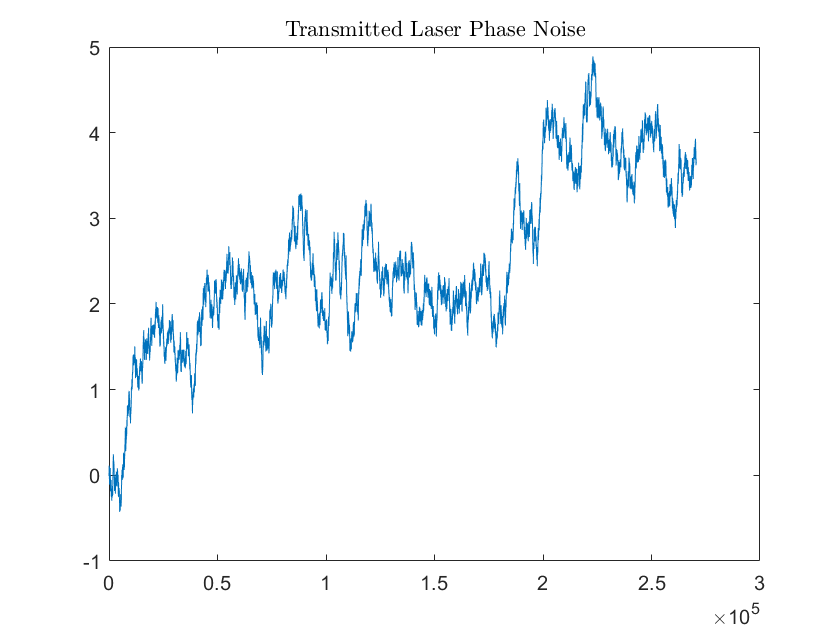

figure();
plot(TX.LASER.phaseNoise)
title('Transmitted Laser Phase Noise','interp','latex')

## Plot Transmitted Constellation Symbols

scatterPlot(S.tx,'markersize:sig',20);
title('IQ Constellation of the Transmitted Symbols','interp','latex')

## Plot Laser Phase Noise

figure();
plot(TX.LASER.phaseNoise)
title('Transmitted Laser Phase Noise','interp','latex')

## Set SNR

S.rx = setSNR(S.txSC,SNR_dB,TX.DAC.RESAMP.sampRate,SIG.symRate);

## Set DSP Parameters

%% Matched-Filter:
DSP.MF.type = 'RRC';
DSP.MF.rollOff = TX.SIG.rollOff;

%% Carrier-Phase Estimation - 1st Stage:
DSP.CPE1.method = 'pilot-based:optimized';
DSP.CPE1.decision = 'data-aided';
% DSP.CPE1.nTaps = 15;
DSP.CPE1.nTaps_min = 1;
DSP.CPE1.nTaps_max = 201;
DSP.CPE1.PILOTS = TX.PILOTS;

%% Carrier-Phase Estimation - 1st Stage:
% DSP.CPE2.method = 'BPS:optimized';
DSP.CPE2.method = 'BPS';
DSP.CPE2.nTaps = 22;
DSP.CPE2.nTaps_min = 1;
DSP.CPE2.nTaps_max = 501;
DSP.CPE2.nTestPhases = 10;
DSP.CPE2.angleInterval = pi/8;

%% Demapper:
DSP.DEMAPPER.normMethod = 'MMSE';

## Apply Matched Filter

S.rx = LPF_apply(S.rx,DSP.MF,TX.DAC.RESAMP.sampRate,SIG.symRate);

## Downsample to 1 Sample/Symbol

S.rx_1sps = S.rx(1:nSpS:end);

## Plot Received Constellation Symbols

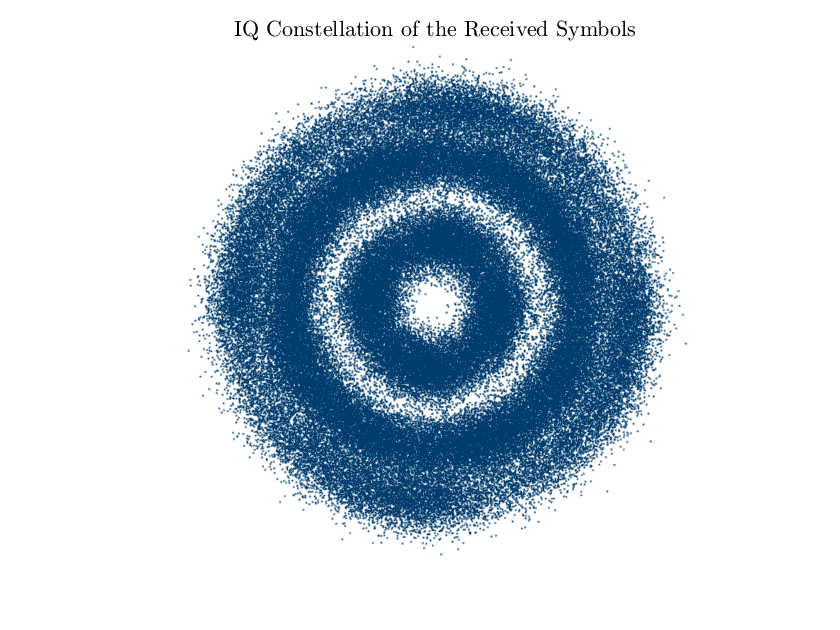

scatterPlot(S.rx_1sps);
title('IQ Constellation of the Received Symbols','interp','latex')

## Apply 1st-Stage CPE: Pilot-Based

[S.rx_1sps,DSP.CPE1] = carrierPhaseEstimation(S.rx_1sps,S.tx,DSP.CPE1);

## Apply 2nd-Stage CPE: Blind-Phase Search

C = TX.QAM.IQmap;
if useCPE2
    [S.rx_1sps,DSP.CPE2] = carrierPhaseEstimation(S.rx_1sps,S.tx,DSP.CPE2,C);
end

## Plot Laser Phase Noise

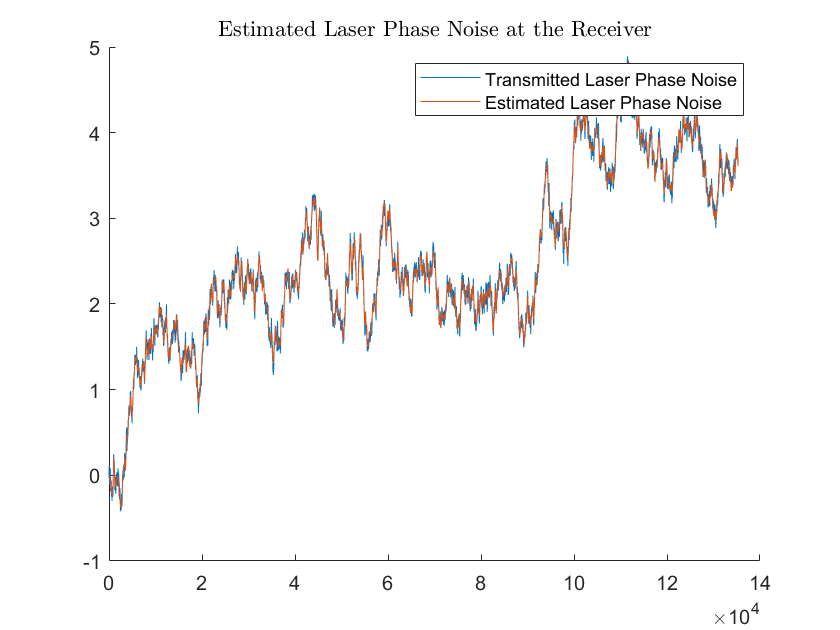

figure();
hold on;
plot(TX.LASER.phaseNoise(1:nSpS:end))
plot(-DSP.CPE1.phi)
legend('Transmitted Laser Phase Noise','Estimated Laser Phase Noise');
title('Estimated Laser Phase Noise at the Receiver','interp','latex');

## Remove DSP Pilots

[S.rx_1sps,S.tx] = pilotSymbols_rmv(S.rx_1sps,S.tx,DSP.CPE1.PILOTS);

## Apply Symbol Demapper

[DSP.DEMAPPER,S.tx] = symDemapper(S.rx_1sps,S.tx,C,DSP.DEMAPPER);

## Calculate Bit-Error Ratio (BER)

[BER,errPos] = BER_eval(DSP.DEMAPPER.txBits,DSP.DEMAPPER.rxBits);

## Calculate Error Vector Magnitude (EVM)

EVM = EVM_eval(S.rx_1sps,S.tx);

## Plot Constellation after Demapping

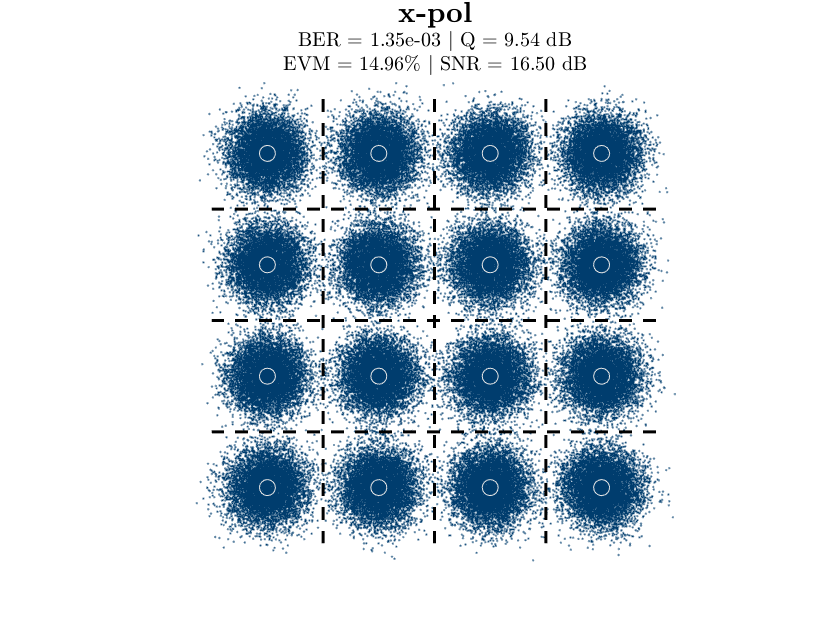

scatterPlot(S.rx_1sps,'BER',BER,'EVM',EVM,'const',DSP.DEMAPPER.C);

% title('IQ Constellation of the Received Symbols After Demapper')

## Exit PROG

exitProg();



Total Elapsed Time: 9.5596 [s]

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%                               END                                %%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
